# Estructuras de selección o condicionales

## Estructura `if/else/elseif`

### Ejercicio 1

El discriminante de una ecuación cuadrática es


$$D=b^2 -4\textrm{ac}$$


Cuando el discriminante es positivo, la ecuación cuadrática tiene 2 raíces reales, pero cuando el discriminante es cero la ecuación cuadrática tiene una única raíz real. Por otra parte, cuando el discriminante es negativo la ecuación cuadrática no tiene raíces reales.

Solicitar al usuario por teclado que ingrese los valores de $a$, $b$ y $c$, y mostrarle por pantalla el discriminante y lo que significa. También desplegar por pantalla las raíces reales, siempre y cuando la ecuación cuadrática las tenga.

*Ejercicio modificado de Gilat, 2005.*

### Solución

a=input("Ingrese el valor de a\n");
b=input("ingrese el avlor de b\n");
c=input("ingrese el valor de c\n");
D=power(b,2)-4*a*c

D = -76

if D>0 
    disp("tiene 2 raices reales")
    raiz1=(-b+sqrt(D))/2*a
    raiz2=(-b-sqrt(D))/2*a
elseif D==0
    disp("Una Raiz real")
    raiz1=(-b)/2*a
else 
    disp("Cero raices reales")
end

Cero raices reales


### Ejercicio 2

Recrear el juego **piedra, papel o tijera**.

**Nota:** El usuario debe jugar contra la computadora, es decir, el usuario ingresa alguna de las opciones (piedra, papel o tijera) y la computadora elije la suya aleatoriamente. Se debe mostrar por pantalla las opciones que hayan elegido y el ganador de la partida.

### Solución

usuario=input("Selecciona piedra, papel o tijera\n","s")

usuario = 'piedra'

computadora=randi([1,3])

computadora = 1

if computadora == 1 
    computadora="tijera"
elseif computadora==2
    computadora="piedra"
else 
    computadora="papel"
end

computadora = "tijera"

disp(computadora)

tijera


if (strcmp(usuario, "tijera") && strcmp(computadora, "tijera")) || (strcmp(usuario, "papel") && strcmp(computadora, "papel")) || (strcmp(usuario, "tijera") && strcmp(computadora, "tijera"))
    disp("Empate")
elseif (strcmp(usuario, "tijera") && strcmp(computadora, "piedra")) || (strcmp(usuario, "piedra") && strcmp(computadora, "papel")) || (strcmp(usuario, "papel") && strcmp(computadora, "tijera"))
    disp("Gana la computadora")
else 
    disp("Gana el usuario")
end

Gana el usuario


### Ejercicio 3

En química, el pH de una solución acuosa es una medida de su acidez. La escala de pH va de 0 a 14. Una solución con un pH de 7 se dice que es neutra, una solución con un pH superior a 7 es básica y una solución con un pH inferior a 7 es ácida. Solicite al usuario el pH de una solución e imprimir si es neutral, básico o ácido. Si el usuario ingresa un pH no válido, se imprimirá un mensaje de error utilizando la función `error`.

**Nota:** Consultar la función `error` en la documentación.

*Ejercicio tomado de Attaway, 2022.*

### Solución

Ph=input("Ingrese una Ph entre 0 y 14\n")

Ph = 7

cond1=Ph<14 & Ph>7

cond1 = logical
   0


cond2=Ph==7

cond2 = logical
   1


cond3=Ph>0 & Ph<7

cond3 = logical
   0



if cond1
    disp("Solución básica")
elseif cond2
    disp("Solución neutra")
elseif cond3
    disp("Solución ácida")
else 
    error("Número no valido")
end

Solución neutra


## Estructura `switch/case/otherwise`

### Ejercicio 1

Con la finalidad de tener una figura geométrica cerrada compuesta de líneas rectas, los ángulos en la figura deben sumar


$$\left(n-2\right)\left(180\;\textrm{grados}\right)$$


donde $n$ es el número de lados.

**Figura 1.** Figuras geométricas.

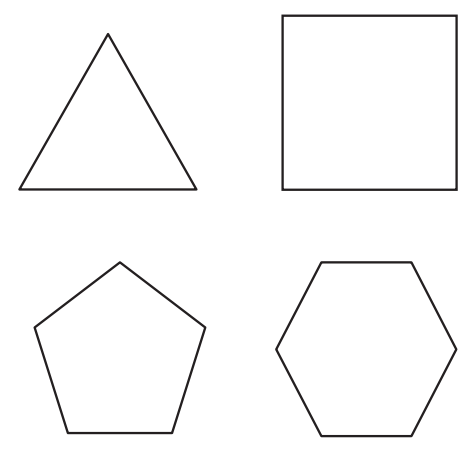

*Tomado de MATLAB para ingenieros de Holly Moore.*

- Pruebe este enunciado usted mismo mediante la creación de un vector llamado `n` desde 3 hasta 6 y calcule la suma de ángulo a partir de la fórmula. Compare lo que sabe de geometría con su respuesta.

- Solicitar al usuario que seleccione la figura trigonométrica entre triángulo, cuadrado, pentágono y exágono. En función de la selección hecha asignar el número de lados y calcular la suma de los ángulos.

**Recomendación:** Para el literal 2 utilizar la función `menu` (consultar la documentación si es necesario).

*Ejercicio modificado de Moore, 2007.*

### Solución 1 

n=randi([3,6])

n = 3

PI=rad2deg(pi);  %180 grados 

PI = 180

Ang=(n-2)*(PI) 

Ang = 180

### **Solución 2 **

PI=rad2deg(pi);  %180 grados 
choice=menu("Selecione una figura: ", ["Triangulo" "Cuadrado" "Pentano" "Hexagono"]);
switch choice 
    case 1 
       n=3;
       Angulo=(n-2)*(PI);
       fprintf("El angulo es: %d°",Angulo)
    case 2 
       n=4;
       Angulo=(n-2)*(PI);
       fprintf("El angulo es: %d°",Angulo)
    case 3 
       n=5;
       Angulo=(n-2)*(PI);
       fprintf("El angulo es: %d°",Angulo)
    case 4 
       n=6;
       Angulo=(n-2)*(PI);
       fprintf("El angulo es: %d°",Angulo)
    otherwise
end

El angulo es: 540°

### Ejercicio 2

En la Universidad de Utah, cada especialización en ingeniería requiere un número diferente de créditos para graduación. Por ejemplo, en 2005, los requisitos para algunos de los departamentos fueron los siguientes:

- Ingeniería civil: 130

- Ingeniería química: 130

- Ingeniería en computación: 122

- Ingeniería eléctrica: 126.5

- Ingeniería mecánica: 129

Solicite al usuario a seleccionar un programa de ingeniería desde un menú (utilizando la función `menu`). Luego, desplegar por pantalla el número mínimo de créditos requeridos para la graduación.

*Ejercicio modificado de Moore, 2007.*

### Solución

opcion=menu("Seleccione una carrera: ",["Ingeniería civil" "Ingeniería química" "Ingeniería en computación" ...
    "Ingeniería eléctrica" "Ingeniería mecánica"]);
switch opcion
    case 1
        disp("Se necesitan 130 creditos")
    case 2
        disp("Se necesitan 130 creditos")
    case 3 
        disp("Se necesitan 122 creditos")
    case 4 
        disp("Se necesitan 126.5 creditos")
    otherwise
        disp("Se necesitan 129 creditos")
end

Se necesitan 126.5 creditos
